# `MATH 3620 Numerical Analysis`

# `Homework 4`

# `03 Mar 2021`

close all; clear all ; clc;

## `Q1. Evaluating Lebesgue Function`

## `1b`

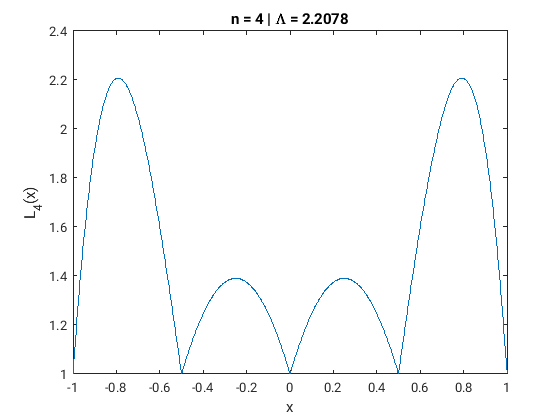

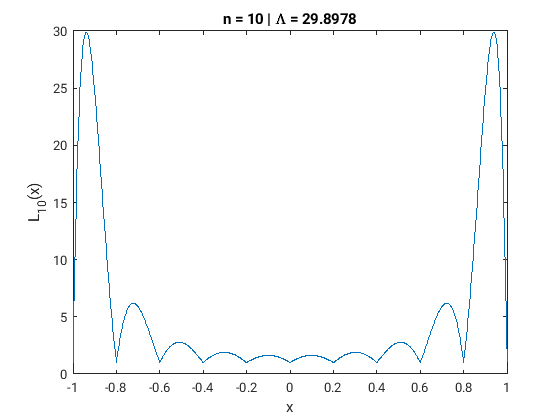

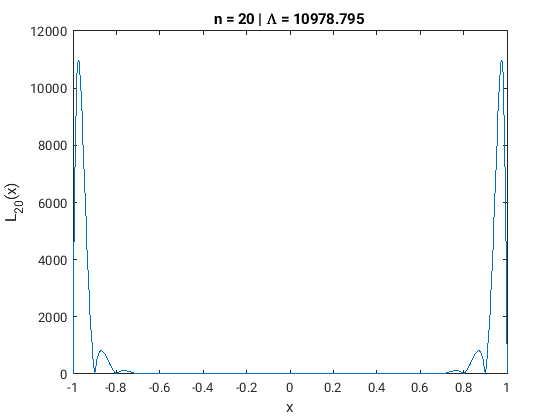

nlist = [4 10 20];

% evaluation points
p = linspace(-1, 1, 1000);

% Inf norm of L_n
Lambda = zeros(size(nlist));

for i = 1:length(nlist)
    n = nlist(i);
    % node vector, t
    j = 0:n;
    t = -1 + j*(2/n);
    % evaluate Lebesgue function
    y = zeros(size(p));
    for j = 1:length(y)
        y(j) = Lebesgue(t, p(j));
    end
    % make plot
    figure()
    plot(p, y)
    % estimate Lambda_n
    Lambda(i) = max(y);
    % add detail to plot
    xlabel('x')
    ystr = ['L_', '{', num2str(n), '}', '(x)'];
    ylabel(ystr)
    titlestr = ['n = ', num2str(n), ' | ', '\Lambda = ', num2str(Lambda(i))];
    title(titlestr)
end

## `1c`

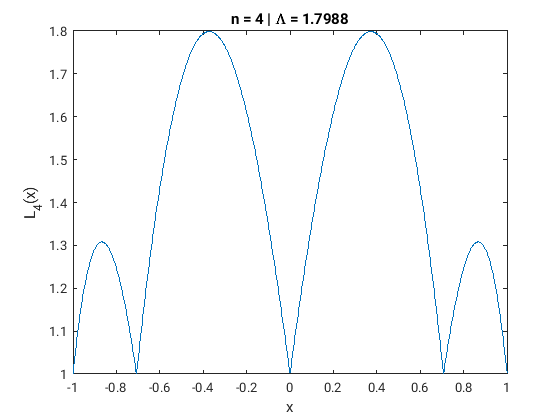

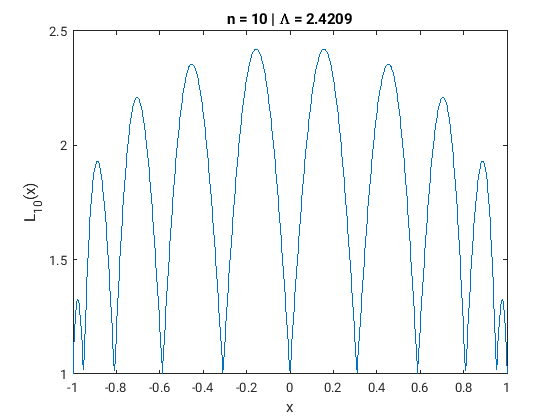

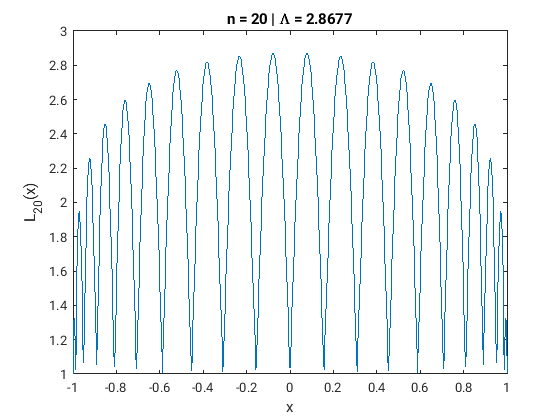

nlist = [4 10 20];

% evaluation points
p = linspace(-1, 1, 1000);

% Inf norm of L_n
Lambda = zeros(size(nlist));

for i = 1:length(nlist)
    n = nlist(i);
    % node vector, t
    j = 0:n;
    t = cos(j*pi/n);
    % evaluate Lebesgue function
    y = zeros(size(p));
    for j = 1:length(y)
        y(j) = Lebesgue(t, p(j));
    end
    % make plot
    figure()
    plot(p, y)
    % estimate Lambda_n
    Lambda(i) = max(y);
    % add detail to plot
    xlabel('x')
    ystr = ['L_', '{', num2str(n), '}', '(x)'];
    ylabel(ystr)
    titlestr = ['n = ', num2str(n), ' | ', '\Lambda = ', num2str(Lambda(i))];
    title(titlestr)
end

`Comments:` `The behavior of the Lebesgue function with equispaced and Gauss-Lobatto nodes are contrasting. In the case of equispaced nodes, the function assumes smaller values inside the interval, and grows to very large values at the ends of the interval, as 'n' increases. Consequently, `$\Lambda$` is very large as well. With the Gauss-Lobato nodes, the function grows as we move towards the center of the interval, but the growth is not drastic and remains within appreciable bounds, because of which the value of `$\Lambda$` is much smaller than observed with equispaced nodes. Additionally, the value of `$\Lambda$` does not increase much for Gauss-Lobatto nodes as 'n' increases, while in the case of equispaced nodes, the value of `$\Lambda$` quickly grows to large values.  `

## `Q2. Barycentric formula for interpolating polynomials`

## `2a`

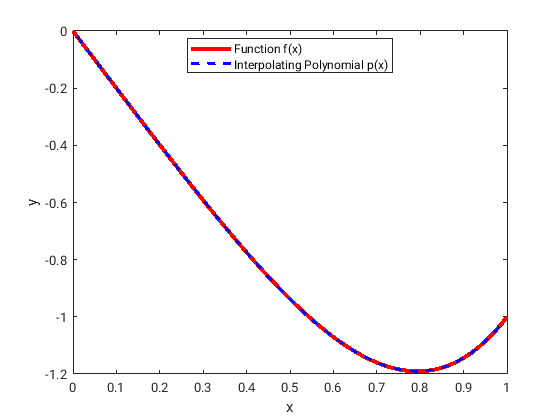

% 5 nodes
x = linspace(0, 1, 5);
% test function of order 4 = (5-1)
f = @(x) x.^4 - 2*x;
% evaluation points
t = linspace(0, 1, 100);
% plot function
plot(t, f(t), "LineWidth", 3, "Color", "Red")
hold on
% plot interpolating polynomial using Barycentric formula
weights = Barycentric(x);
p = zeros(size(t));
for i = 1:length(p)
    num = 0; denum = 0;
    for j = 1:length(x)
        num = num + weights(j)*f(x(j))/(t(i) - x(j));
        denum = denum + weights(j)/(t(i) - x(j));
    end
    p(i) = num/denum;
end
plot(t, p, "LineStyle","--", "Color","Blue", "LineWidth", 2)
hold off
xlabel('x')
ylabel('y')
legend('Function f(x)', 'Interpolating Polynomial p(x)', "Location", "best")

## `2b`

x = [0.00 0.25 0.52 0.74 1.28 1.50];
f = [0.0000 0.7070 1.0000 0.7071 -0.7074 -1.0000];

% find P_5(2) as an approximation to f(2)
weights = Barycentric(x);
t = 2;
num = 0; denum = 0;
for j = 1:length(x)
    num = num + weights(j)*f(j)/(t - x(j));
    denum = denum + weights(j)/(t - x(j));
end
p = num/denum;
fprintf('P_5(2) = %.4f\n', p)

P_5(2) = -2.3438


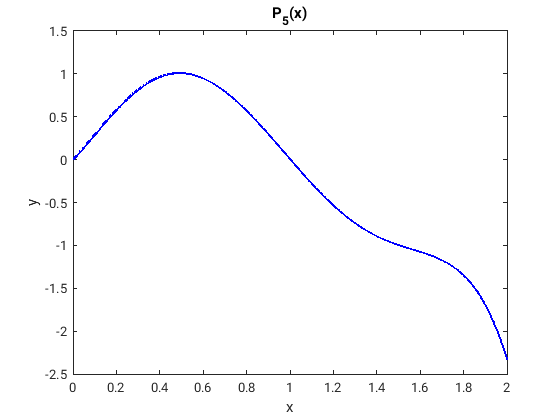

% plot P_5(x)
t = linspace(0, 2, 1000);
p = zeros(size(t));
for i = 1:length(p)
    num = 0; denum = 0;
    for j = 1:length(x)
        num = num + weights(j)*f(j)/(t(i) - x(j));
        denum = denum + weights(j)/(t(i) - x(j));
    end
    p(i) = num/denum;
end
plot(t, p, "Color","Blue", "LineWidth", 2)
xlabel('x')
ylabel('y')
title('P_5(x)')

## `Q3. Runge's Phenomenon`

## `3a`

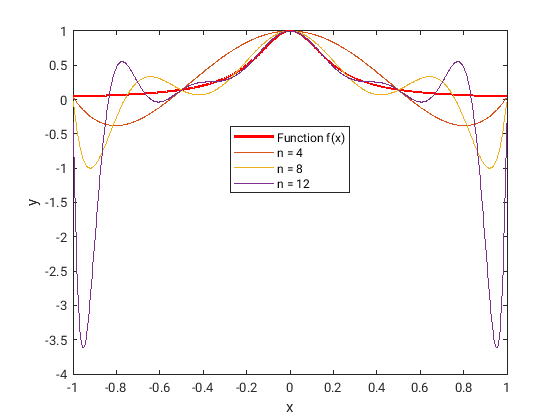

f = @(x) 1./(1 + 25*x.*x);
t = linspace(-1, 1, 1000);

% plot function
plot(t, f(t), "LineWidth", 2, "Color", "Red")
hold on

% plot interpolating polynomial using Barycentric formula
legendstr = [];
nlist = [4 8 12];
for k = 1:length(nlist)
    n = nlist(k);
    j = 0:n;
    % equispaced nodes
    nodes = -1 + j*(2/n);
    weights = Barycentric(nodes);
    p1 = zeros(size(t));
    for i = 1:length(p)
        num = 0; denum = 0;
            for j = 1:length(nodes)
                num = num + weights(j)*f(nodes(j))/(t(i) - nodes(j));
                denum = denum + weights(j)/(t(i) - nodes(j));
            end
        p1(i) = num/denum;
    end
plot(t, p1, "LineWidth", 1)
legendstr = [legendstr, ["n = " + num2str(n)]];
end
legendstr = ["Function f(x)", legendstr];
hold off
xlabel('x')
ylabel('y')
legend(legendstr, "Location", "best")

## `3b`

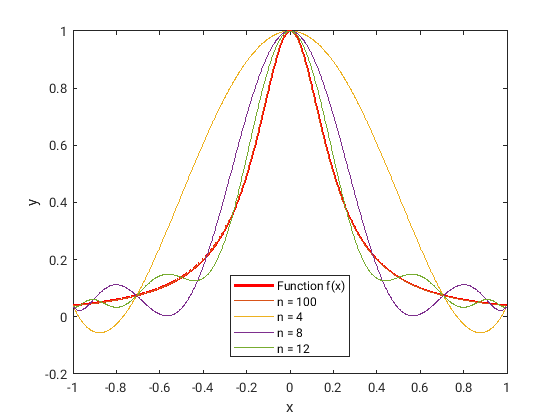

% plot function
plot(t, f(t), "LineWidth", 2, "Color", "Red")
hold on

% plot interpolating polynomial using Barycentric formula
legendstr = [];
nlist = [100 4 8 12];
for k = 1:length(nlist)
    n = nlist(k);
    j = 0:n;
    % chebyshev nodes
    nodes = cos(j*pi/n);
    weights = Barycentric(nodes);
    p2 = zeros(size(t));
    for i = 1:length(p)
        num = 0; denum = 0;
            for j = 1:length(nodes)
                num = num + weights(j)*f(nodes(j))/(t(i) - nodes(j));
                denum = denum + weights(j)/(t(i) - nodes(j));
            end
        p2(i) = num/denum;
    end
plot(t, p2, "LineWidth", 1)
legendstr = [legendstr, ["n = " + num2str(n)]];
end
legendstr = ["Function f(x)", legendstr];
hold off
xlabel('x')
ylabel('y')
legend(legendstr, "Location", "best")

## `3c`

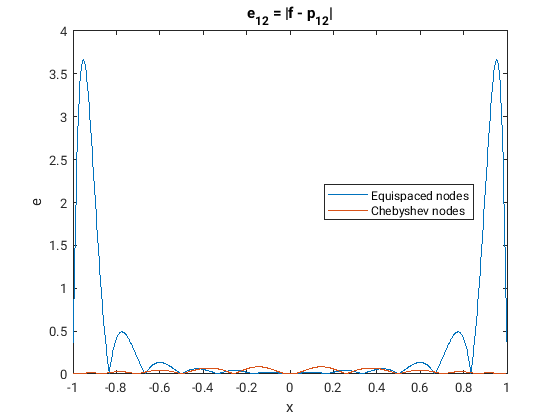

% plot errors
e1 = abs(f(t) - p1);
e2 = abs(f(t) - p2);
plot(t, e1)
hold on
plot(t, e2)
hold off
xlabel('x')
ylabel('e')
title('e_{12} = |f - p_{12}|')
legend('Equispaced nodes', 'Chebyshev nodes', "Location", "best")

`Comments:`` We see that the equispaced nodes result in lesser error in the central region of the interval, but the errors grow very fast as we approach the ends of the interval. In contrast to this, the errors with Chebyshev nodes stay bounded over the whole interval, and decrease as we move towards the ends of the interval. The largest error with Chebyshev nodes is a fraction of the max error with equispaced nodes. The plot above clearly shows that Chebyshev nodes are a much superior choice when it comes to improving quality of interpolation.`

## `3d`

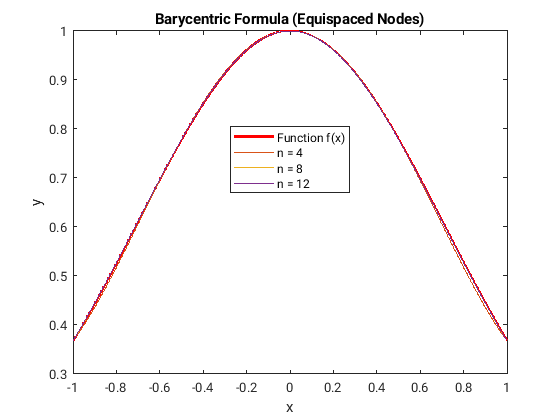

f = @(x) exp(-x.*x);
t = linspace(-1, 1, 1000);

% plot function
figure()
plot(t, f(t), "LineWidth", 2, "Color", "Red")
hold on

% plot interpolating polynomial using Barycentric formula
legendstr = [];
nlist = [4 8 12];
for k = 1:length(nlist)
    n = nlist(k);
    j = 0:n;
    % equispaced nodes
    nodes = -1 + j*(2/n);
    weights = Barycentric(nodes);
    p1 = zeros(size(t));
    for i = 1:length(p)
        num = 0; denum = 0;
            for j = 1:length(nodes)
                num = num + weights(j)*f(nodes(j))/(t(i) - nodes(j));
                denum = denum + weights(j)/(t(i) - nodes(j));
            end
        p1(i) = num/denum;
    end
    plot(t, p1, "LineWidth", 1)
    legendstr = [legendstr, ["n = " + num2str(n)]];
end
legendstr = ["Function f(x)", legendstr];
hold off
xlabel('x')
ylabel('y')
legend(legendstr, "Location", "best")
title('Barycentric Formula (Equispaced Nodes)')

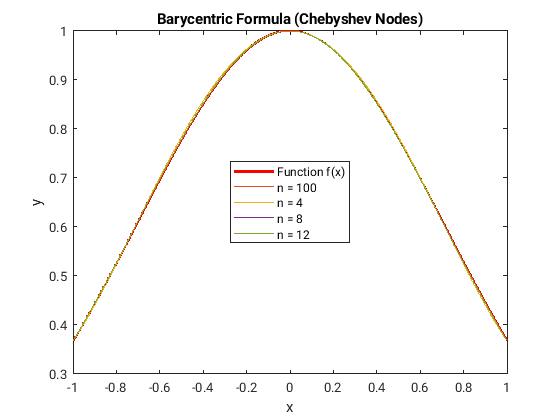


% plot function
figure()
plot(t, f(t), "LineWidth", 2, "Color", "Red")
hold on

% plot interpolating polynomial using Barycentric formula
legendstr = [];
nlist = [100 4 8 12];
for k = 1:length(nlist)
    n = nlist(k);
    j = 0:n;
    % chebyshev nodes
    nodes = cos(j*pi/n);
    weights = Barycentric(nodes);
    p2 = zeros(size(t));
    for i = 1:length(p)
        num = 0; denum = 0;
            for j = 1:length(nodes)
                num = num + weights(j)*f(nodes(j))/(t(i) - nodes(j));
                denum = denum + weights(j)/(t(i) - nodes(j));
            end
        p2(i) = num/denum;
    end
    plot(t, p2, "LineWidth", 1)
    legendstr = [legendstr, ["n = " + num2str(n)]];
end
legendstr = ["Function f(x)", legendstr];
hold off
xlabel('x')
ylabel('y')
legend(legendstr, "Location", "best")
title('Barycentric Formula (Chebyshev Nodes)')

## `Q4. Newton's Interpolating Polynomial`

## `4b`

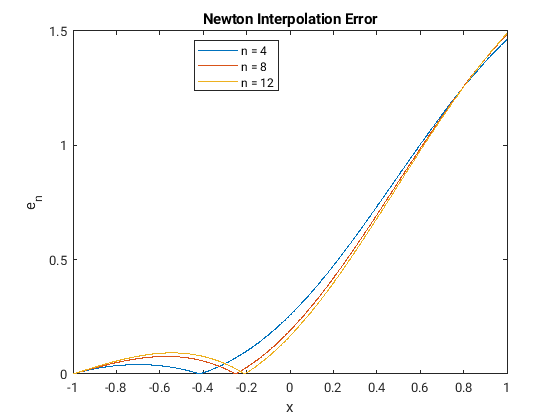

f = @(x) exp(-x.*x);
% evaluation points
t = linspace(-1, 1, 1000);

% legend string
legendstr = [];

nlist = [4 8 12];
for k = 1:length(nlist)
    n = nlist(k);
    j = 0:n;
    nodes = -1 + j*(2/n);
    % get coefficients
    c = NewtonInterp(nodes, f(nodes));
    % evaluate p
    p = zeros(size(t));
    for i = 1:length(p)
        p(i) = c(end);
        for j = n:-1:1
            p(i) = c(j) + (t(i) - nodes(j))*p(i);
        end
    end
    % plot errors
    plot(t, abs(f(t) - p))
    hold on
    legendstr = [legendstr, ["n = " + num2str(n)]];
end
xlabel('x')
ylabel('e_n')
legend(legendstr, "Location", "best")
title('Newton Interpolation Error')
hold off

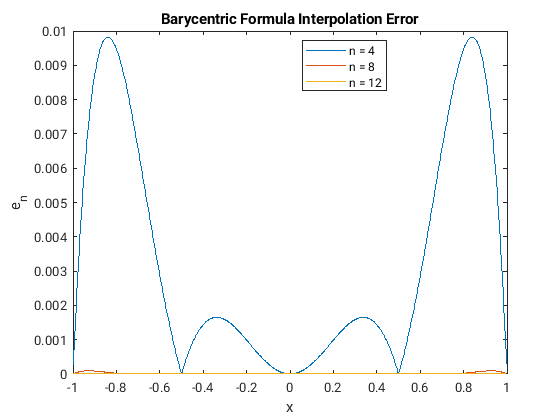


% errors in 3d (equispaced nodes)
f = @(x) exp(-x.*x);
t = linspace(-1, 1, 1000);

figure()
legendstr = [];
nlist = [4 8 12];
for k = 1:length(nlist)
    n = nlist(k);
    j = 0:n;
    % equispaced nodes
    nodes = -1 + j*(2/n);
    weights = Barycentric(nodes);
    p1 = zeros(size(t));
    for i = 1:length(p)
        num = 0; denum = 0;
            for j = 1:length(nodes)
                num = num + weights(j)*f(nodes(j))/(t(i) - nodes(j));
                denum = denum + weights(j)/(t(i) - nodes(j));
            end
        p1(i) = num/denum;
    end
    plot(t, abs(f(t) - p1), "LineWidth", 1)
    hold on
    legendstr = [legendstr, ["n = " + num2str(n)]];
end
hold off
xlabel('x')
ylabel('e_n')
legend(legendstr, "Location", "best")
title('Barycentric Formula Interpolation Error')

`Comments:`` The Barycentric Formula performs superior to the Newton Interpolating Polynomial, which can be clearly seen from the plots for 3(d). The interpolant and the function are almost indistinguishable even for 'n = 4'. The order of errors obtained with Newton Interpolating polynomial is much higher (almost 4 orders higher) than those obtained using the Barycentric formula.`

## `Q5. Inverse Interpolation`

## `5a`

f = @(x) x - exp(-x);
f(0.5)

ans = -0.1065

f(0.6)

ans = 0.0512

`As we can see above, the function 'f' goes from negative value to a positive value in the interval [0.5 0.6]. Since the function is continuous, we know from basic algebra that 'f' must have a root in the interval [0.5 0.6]. Hence, we can use the values f(0.5) and f(0.6) to find a zero of f(x).`

## `5b`

x = [f(0.5) f(0.6)];
y = [0.5 0.6];
f01 = (y(2) - y(1))/(x(2) - x(1));
p1 = y(1) + f01*(0 - x(1))

p1 = 0.5675

x = [x f(p1)];
y = [y p1];
f12 = (y(3) - y(2))/(x(3) - x(2));
f012 = (f12 - f01)/(x(3) - x(1));
p2 = p1 + f012*(0 - x(1))*(0 - x(2))

p2 = 0.5671

 `The approximate value of the zero of the function 'f' is 0.5671.`

## `FUNCTION DEFINITIONS`

## `1a`

function val = Lebesgue(t, x)
    % t = node vector
    % x = input for the Lebesgue function
    % val = L_n(x)
    
    % compute lagrange polynomials
    lp = ones(size(t));
    for i = 1:length(t)
        for j = 1:length(t)
            if j ~= i
                lp(i) = lp(i)*(x - t(j))/(t(i) - t(j));
            end
        end
    end
    val = sum(abs(lp));
end

## `2`

function w = Barycentric(x)
    % x = nodes
    % w = barycentric weights
    
    w = ones(size(x));
    for i = 1:length(x)
        for j = 1:length(x)
            if j ~= i
                w(i) = w(i)*(x(i) - x(j));
            end
        end
    end
    w = 1./w;
end

## `4a`

function c = NewtonInterp(x, f)
    % x = nodes
    % f = function values at nodes
    % c = coefficients of the Newton Interpolating Polynomial
    
    c = zeros(size(x));
    n = length(x) - 1;
    for j = 0:n
        c(j+1) = f(j+1);
    end
    for k = 2:n+1
        for j = n+1:-1:k+1
            c(j) = (c(j) - c(j-1))/(x(j) - x(j - k));
        end
    end
end